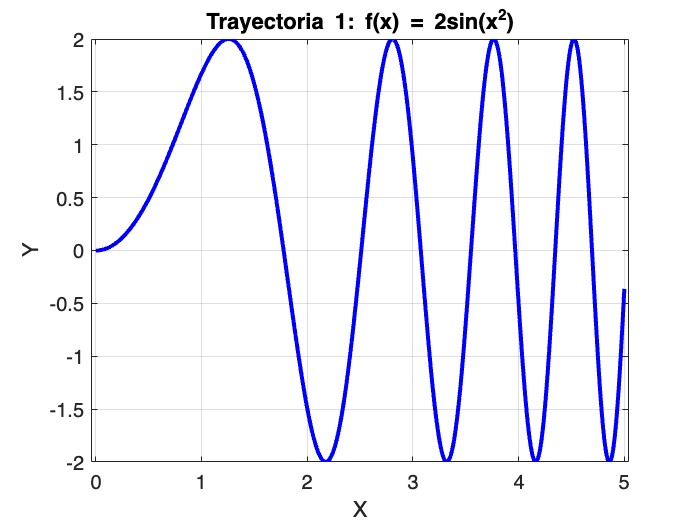

ts = 0.01;  % Paso de tiempo para simulación

%% Trayectoria 1: f(x) = 2 * sin(x^2)
x1 = 0:ts:5;
y1 = 2 * sin(x1.^2);
dy1 = 4 * x1 .* cos(x1.^2);
theta1 = atan(dy1);
v1 = sqrt(1 + dy1.^2);
omega1 = gradient(theta1, ts);

xpos1 = zeros(size(x1));
ypos1 = zeros(size(x1));
for i = 2:length(x1)
    xpos1(i) = xpos1(i-1) + v1(i-1) * cos(theta1(i-1)) * ts;
    ypos1(i) = ypos1(i-1) + v1(i-1) * sin(theta1(i-1)) * ts;
end

figure
plot(xpos1, ypos1, 'b', 'LineWidth', 2)
title('Trayectoria 1: f(x) = 2sin(x^2)')
xlabel('X')
ylabel('Y')
axis equal
grid on

Se simula el recorrido de un robot sobre una curva oscilante generada por la función y=2sin (x2)y=2sin(x2). Se calcula la derivada para estimar la orientación en cada punto, y con ella se obtienen las velocidades lineal y angular. Estas velocidades se integran paso a paso para reconstruir la trayectoria en el plano, respetando la curvatura de la función original.

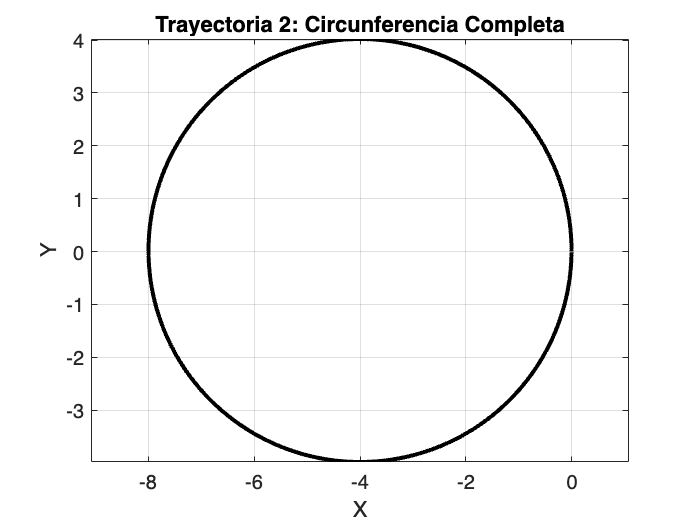

%% Trayectoria 2: Circunferencia completa (x^2 + y^2 = 16)
r = 4;
theta2 = 0:ts:(2*pi);
x2 = r * cos(theta2);
y2 = r * sin(theta2);

dx = gradient(x2, ts);
dy = gradient(y2, ts);
orient2 = atan2(dy, dx);
v2 = sqrt(dx.^2 + dy.^2);
omega2 = gradient(orient2, ts);

xpos2 = zeros(size(x2));
ypos2 = zeros(size(x2));
for i = 2:length(x2)
    xpos2(i) = xpos2(i-1) + v2(i-1) * cos(orient2(i-1)) * ts;
    ypos2(i) = ypos2(i-1) + v2(i-1) * sin(orient2(i-1)) * ts;
end

figure
plot(xpos2, ypos2, 'k', 'LineWidth', 2)
title('Trayectoria 2: Circunferencia Completa')
xlabel('X')
ylabel('Y')
axis equal
grid on

El robot sigue una circunferencia de radio constante r=4r=4 utilizando una parametrización angular. A partir de las coordenadas x=rcos (θ),y=rsin (θ)x=rcos(θ),y=rsin(θ), se obtienen orientación, velocidad lineal y angular, que permiten simular un movimiento circular completo mediante integración temporal.

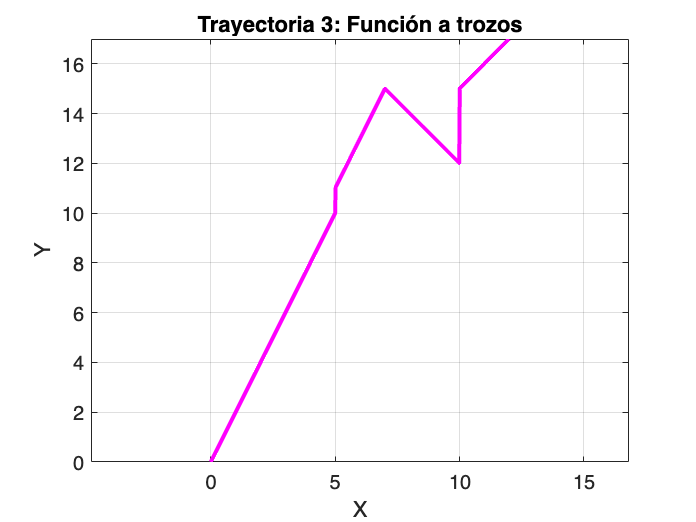

%% Trayectoria 3: Función a trozos
x3 = -6:ts:6;
y3 = zeros(size(x3));
for i = 1:length(x3)
    xi = x3(i);
    if xi <= -1
        y3(i) = 2 * xi;
    elseif xi > -1 && xi < 1
        y3(i) = 2 * xi + 1;
    elseif xi >= 1 && xi < 4
        y3(i) = -xi + 4;
    else
        y3(i) = xi - 1;
    end
end

dy3 = gradient(y3, ts);
theta3 = atan(dy3);
v3 = sqrt(1 + dy3.^2);
omega3 = gradient(theta3, ts);

xpos3 = zeros(size(x3));
ypos3 = zeros(size(x3));
for i = 2:length(x3)
    xpos3(i) = xpos3(i-1) + v3(i-1) * cos(theta3(i-1)) * ts;
    ypos3(i) = ypos3(i-1) + v3(i-1) * sin(theta3(i-1)) * ts;
end

figure
plot(xpos3, ypos3, 'm', 'LineWidth', 2)
title('Trayectoria 3: Función a trozos')
xlabel('X')
ylabel('Y')
axis equal
grid on

Esta trayectoria está compuesta por varios tramos definidos por condiciones sobre x. Se evalúa la función a trozos y se calcula su derivada numérica para obtener orientación y velocidades. Mediante integración de estas velocidades, se genera una trayectoria continua que respeta la forma segmentada de la función definida.